# Mehdi Muzaffari - MAE 674 - Project 1

clc;
clear;
close all;

## load simulated Data

data = readtable('simulation');
time = data.Time;
theta1_true = data.Theta1;
theta1_dot_true = data.Theta1_Dot;
theta2_true = data.Theta2;
theta2_dot_true = data.Theta2_Dot;

## add noise to data

noise_std_theta1 = 0.05;
noise_std_theta1_dot = 0.03;
noise_std_theta2 = 0.04;
noise_std_theta2_dot = 0.02;

theta1_measured = theta1_true + noise_std_theta1 * randn(size(theta1_true));
theta1_dot_measured = theta1_dot_true + noise_std_theta1_dot * randn(size(theta1_dot_true));
theta2_measured = theta2_true + noise_std_theta2 * randn(size(theta2_true));
theta2_dot_measured = theta2_dot_true + noise_std_theta2_dot * randn(size(theta2_dot_true));

## simulation parameters

dt = 0.01;
num_steps = length(time);

theta1 = pi/4;
theta1_dot = 0;
theta2 = pi/6;
theta2_dot = 0;

x_hat = [pi/4; 0; pi/6; 0];
P = diag([0.01, 0.1, 0.01, 0.01]);
Q = diag([0.01, 0.01, 0.01, 0.01]);
R = diag([0.05, 0.05, 0.05, 0.05]);

## ukf parameters

alpha = 1e-3;
kappa = 0;
beta = 2;
n = 4;
lambda = alpha.^2 * (n + kappa) - n;
gamma = sqrt(n + lambda);

Wm = [lambda / (n + lambda), repmat(0.5 / (n + lambda), 1, 2 * n)];
Wc = Wm;
Wc(1) = Wc(1) + (1 - alpha^2 + beta);

x_hat_history = zeros(n, num_steps);
P_hat_history = zeros(n, n, num_steps);

x_hat_history(:, 1) = x_hat;
P_hat_history(:, :, 1) = P;

noise_levels = 0.01:0.01:0.1;
rmse_results = zeros(length(noise_levels), 4);

for j = 1: length(noise_levels)

    noise_std_theta1 = noise_levels(j);
    noise_std_theta1_dot = noise_levels(j);
    noise_std_theta2 = noise_levels(j);
    noise_std_theta2_dot = noise_levels(j);

    theta1_measured = theta1_true + noise_std_theta1 * randn(size(theta1_true));
    theta1_dot_measured = theta1_dot_true + noise_std_theta1_dot * randn(size(theta1_dot_true));
    theta2_measured = theta2_true + noise_std_theta2 * randn(size(theta2_true));
    theta2_dot_measured = theta2_dot_true + noise_std_theta2_dot * randn(size(theta2_dot_true));

    R = diag([noise_std_theta1, noise_std_theta1_dot, noise_std_theta2, noise_std_theta2_dot]);

    error_history = zeros(4, num_steps);

    for k = 2:num_steps

        X = [x_hat, x_hat + gamma * chol(P)', x_hat - gamma * chol(P)'];

        X_pred = zeros(size(X));

        for i = 1:size(X, 2)

            theta1 = X(1, i);
            theta1_dot = X(2, i);
            theta2 = X(3, i);
            theta2_dot = X(4, i);

            [theta1_ddot, theta2_ddot] = dynamic(theta1, theta1_dot, theta2, theta2_dot);

            X_pred(:, i) = [theta1 + dt * theta1_dot; theta1_dot + dt * theta1_ddot;
                theta2 + dt * theta2_dot; theta2_dot + dt * theta2_ddot];
        end

        x_pred = X_pred * Wm';

        P_pred = Q;
        for i = 1:size(X, 2)
            P_pred = P_pred +  Wc(i) * (X_pred(:, i) - x_pred) * (X_pred(:, i) - x_pred)';
        end

        X_update = [x_pred, x_pred + gamma * chol(P_pred)', x_pred - gamma * chol(P_pred)'];

        Z_pred = X_update;
        z_pred = Z_pred * Wm';

        S = R;
        for i = 1:size(X_update, 2)
            S = S + Wc(i) * (Z_pred(:, i) - z_pred) * (Z_pred(:, i) - z_pred)';
        end

        C = zeros(n);
        for i = 1:size(X_update, 2)
            C = C + Wc(i) * (X_pred(:, i) - x_pred) * (Z_pred(:, i) - z_pred)';
        end

        K = C / S;
        z = [theta1_measured(k); theta1_dot_measured(k); theta2_measured(k); theta2_dot_measured(k)];
        x_hat = x_pred + K * (z - z_pred);
        P = P_pred - K * S * K';

        x_hat_history(:, k) = x_hat;
        P_hat_history(:, :, k) = P;

        error_history(:, k) = [theta1_true(k); theta1_dot_true(k); theta2_true(k); theta2_dot_true(k)] - x_hat;
    end

    rmse_results(j, :) = sqrt(mean(error_history.^2, 2));
end

disp(array2table(rmse_results, ...
    'VariableNames', {'Theta1', 'Theta1_Dot', 'Theta2', 'Theta2_Dot'}, ...
    'RowNames', cellstr(num2str(noise_levels'))));

             Theta1      Theta1_Dot     Theta2      Theta2_Dot
            _________    __________    _________    __________

    0.01    0.0060467    0.0066479     0.0060733    0.0071955 
    0.02     0.017187      0.01214       0.01875      0.01409 
    0.03     0.021051     0.016779      0.022871     0.019335 
    0.04        0.025     0.020662      0.026907     0.024045 
    0.05     0.028505      0.02539      0.030215     0.028663 
    0.06     0.030795     0.028713      0.033283     0.032979 
    0.07     0.034421      0.03345      0.036672     0.037916 
    0.08     0.036756     0.037634      0.039683     0.041641 
    0.09      0.03932     0.042186      0.041632      0.04612 
    0.1 <

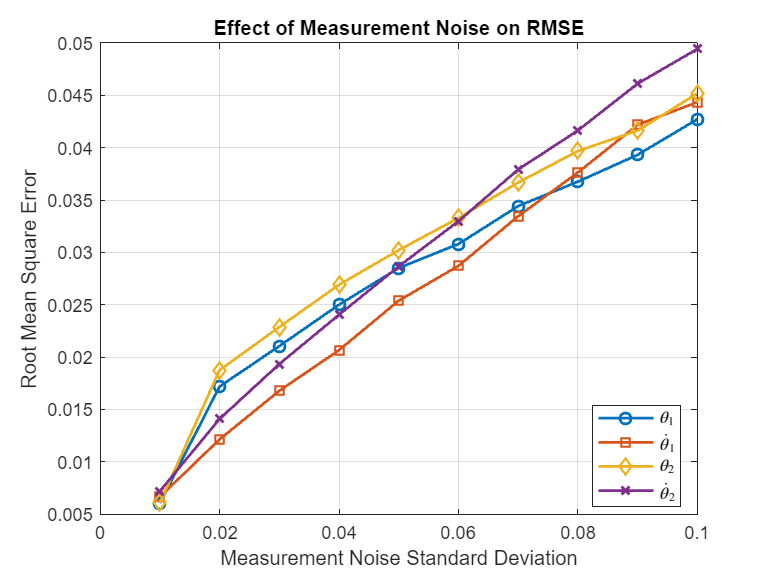

figure;
plot(noise_levels, rmse_results(:, 1), '-o', 'DisplayName', '$\theta_1$', 'LineWidth', 1.5);
hold on;
plot(noise_levels, rmse_results(:, 2), '-s', 'DisplayName', '$\dot{\theta}_1$', 'LineWidth', 1.5);
plot(noise_levels, rmse_results(:, 3), '-d', 'DisplayName', '$\theta_2$', 'LineWidth', 1.5);
plot(noise_levels, rmse_results(:, 4), '-x', 'DisplayName', '$\dot{\theta}_2$', 'LineWidth', 1.5);
xlabel('Measurement Noise Standard Deviation');
ylabel('Root Mean Square Error');
title('Effect of Measurement Noise on RMSE');
legend('Location','best', 'Interpreter', 'Latex');
grid on;
hold off;